% Load the CSV data
data_truth = readtable('./MH01/data.csv');

data_estimate = readtable('./MH01/output.csv');
timestamp_data_truth = (data_truth{:, 1} - data_truth{1,1});
timestamp_data_estimate = (data_estimate{:, 1} - data_estimate{1,1});

% --------------------- Orientation Data -------------------
% Extract relevant columns
qx = data_truth.q_RS_x__;              % Quaternion x
qy = data_truth.q_RS_y__;              % Quaternion y
qz = data_truth.q_RS_z__;              % Quaternion z
qw = data_truth.q_RS_w__;             % Quaternion w

% Initialize arrays for Euler angles
roll = zeros(size(timestamp_data_truth));
pitch = zeros(size(timestamp_data_truth));
yaw = zeros(size(timestamp_data_truth));

% Convert quaternion to Euler angles
for i = 1:length(timestamp_data_truth)
    % Extract quaternion components
    qx_i = qx(i);
    qy_i = qy(i);
    qz_i = qz(i);
    qw_i = qw(i);

    % Roll (x-axis rotation)
    sinr_cosp = 2 * (qw_i * qx_i + qy_i * qz_i);
    cosr_cosp = 1 - 2 * (qx_i^2 + qy_i^2);
    roll(i) = atan2(sinr_cosp, cosr_cosp);

    % Pitch (y-axis rotation)
    sinp = 2 * (qw_i * qy_i - qz_i * qx_i);
    if abs(sinp) >= 1
        pitch(i) = sign(sinp) * pi / 2; % Use 90 degrees if out of range
    else
        pitch(i) = asin(sinp);
    end

    % Yaw (z-axis rotation)
    siny_cosp = 2 * (qw_i * qz_i + qx_i * qy_i);
    cosy_cosp = 1 - 2 * (qy_i^2 + qz_i^2);
    yaw(i) = atan2(siny_cosp, cosy_cosp);
end

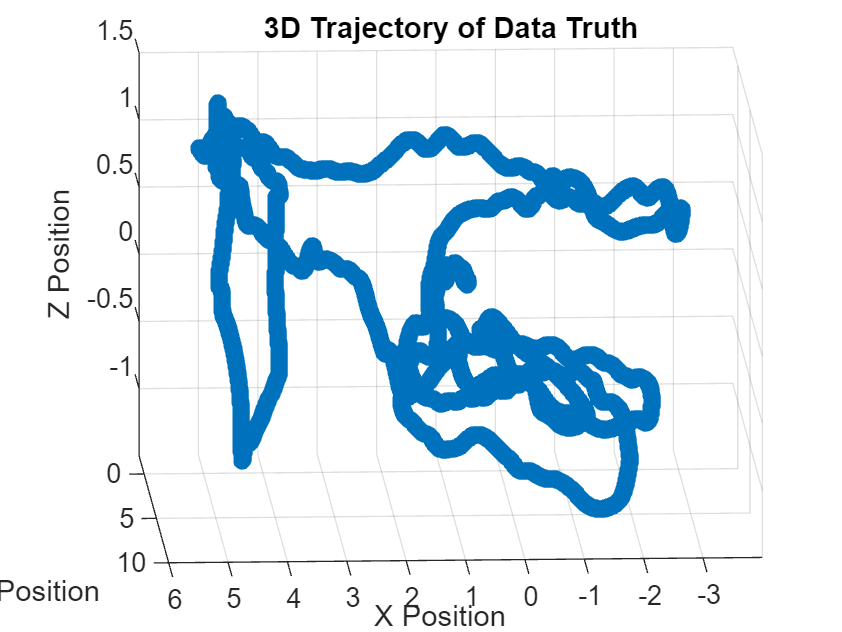

% --------------------- Position Data ------------------- 
% Extract position columns 
x_truth = data_truth.p_RS_R_x_m_; 
y_truth = data_truth.p_RS_R_y_m_; 
z_truth = data_truth.p_RS_R_z_m_; 
% Plot the 3D trajectory 
figure; 
plot3(x_truth, y_truth, z_truth, '-o'); 
grid on; 
xlabel('X Position'); 
ylabel('Y Position'); 
zlabel('Z Position'); 
title('3D Trajectory of Data Truth');

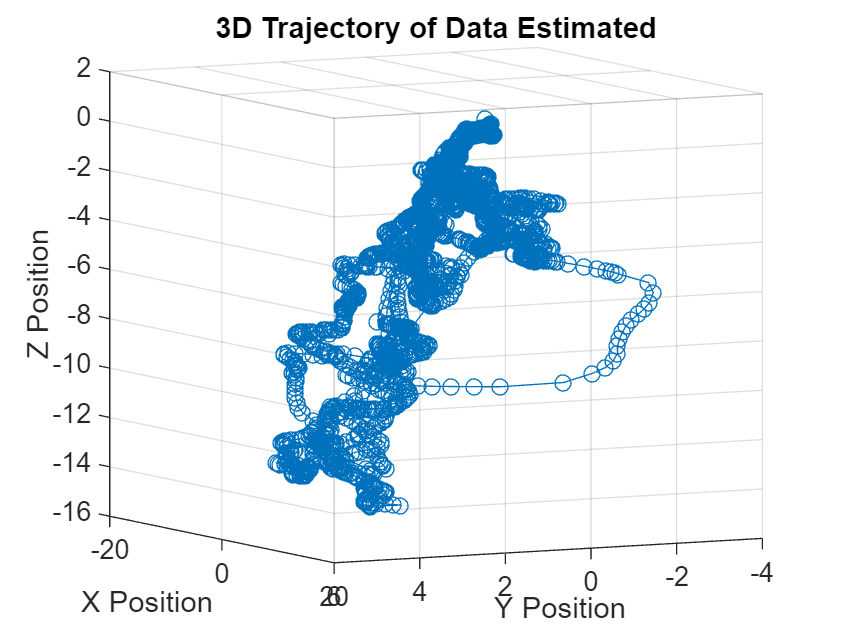

% --------------------- Position Data ------------------- 
% Extract position columns 
x_est = data_estimate.Var4; 
y_est = data_estimate.Var5; 
z_est = data_estimate.Var6; 
% Plot the 3D trajectory 
figure; 
plot3(x_est, y_est, z_est, '-o'); 
grid on; 
xlabel('X Position'); 
ylabel('Y Position'); 
zlabel('Z Position'); 
title('3D Trajectory of Data Estimated');

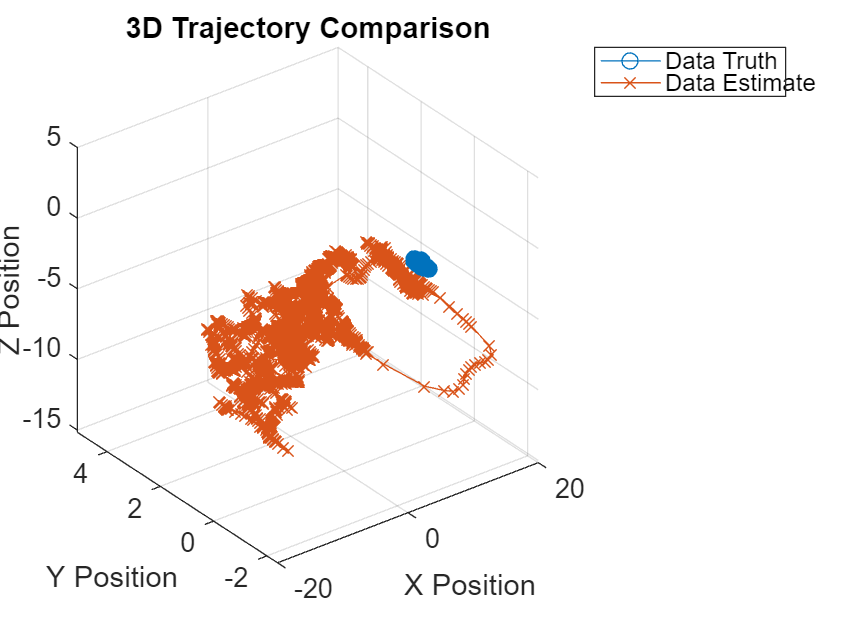

% Determine the shorter length
min_length = min(length(x_truth), length(x_est));

% Plot the 3D trajectory for both datasets
figure; 
plot3(x_truth(1:min_length), y_truth(1:min_length), z_truth(1:min_length), '-o', 'DisplayName', 'Data Truth'); 
hold on;
plot3(x_est(1:min_length), y_est(1:min_length), z_est(1:min_length), '-x', 'DisplayName', 'Data Estimate');
grid on; 
xlabel('X Position'); 
ylabel('Y Position'); 
zlabel('Z Position'); 
title('3D Trajectory Comparison'); 
legend show;

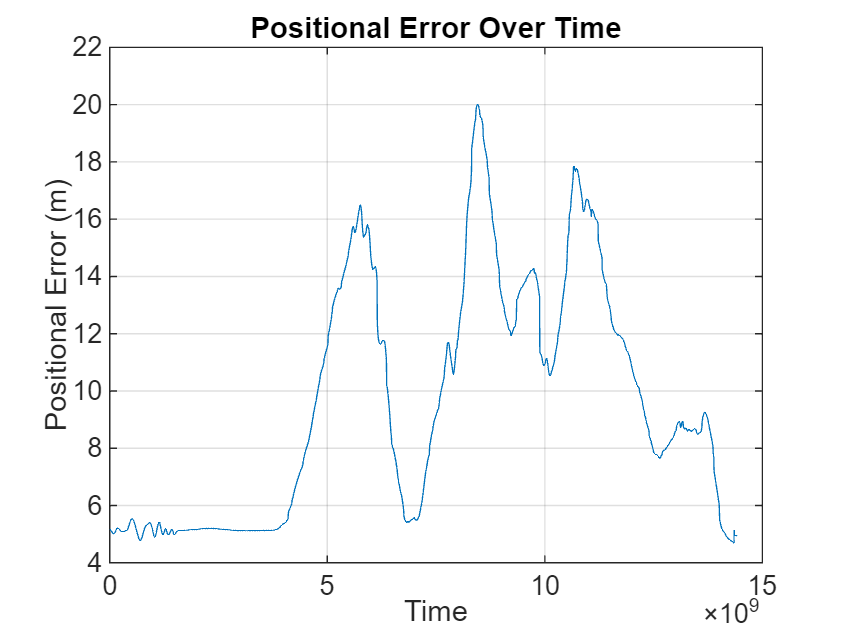


% Calculate positional error
positional_error = sqrt((x_truth(1:min_length) - x_est(1:min_length)).^2 + ...
                        (y_truth(1:min_length) - y_est(1:min_length)).^2 + ...
                        (z_truth(1:min_length) - z_est(1:min_length)).^2);

% Plot the positional error over time
figure;
plot(timestamp_data_truth(1:min_length), positional_error, '-');
grid on;
xlabel('Time');
ylabel('Positional Error (m)');
title('Positional Error Over Time');